Список портов

seriallist


Настроить порт


s = serial("COM5",'BaudRate',115200,'InputBufferSize',4096,'OutputBufferSize',4096);
if exist('s','var')==1
    fclose(s);
end
newobjs = instrfind;
fclose(newobjs);
clear newobjs;

DSP_LEN = 1024;

Проверка связи

fopen(s);
cmd = [0 1 2 3];
fwrite(s,cmd,'uint8');
dataIn = fread(s,4);
disp(dataIn);
fclose(s);
clear dataIn cmd

Получить входной буфер от STM ------>

fopen(s);
cmd = [1 1];
fwrite(s,cmd,'uint16');
dataIn = fread(s,length(cmd),'uint16');
dataInCmd = dataIn(1,1);
if dataInCmd == 11
    DSP_LEN = dataIn(2,1);
    inputBuf = zeros([DSP_LEN,1],'single');
    for n = 1:DSP_LEN
        inputBuf(n,1) = fread(s,1,'single');
    end
end
fclose(s);
disp(inputBuf);

       13240
       13714
       14206
       14695
       15193
       15508
       16265
       16817
       17359
       17920
       18490
       19063
       19644
       20245
       20841
       21456
       22071
       22699
       23334
       23967
       24600
       25252
       25898
       26554
       27208
       27861
       28524
       29194
       29855
       30532
       31202
       31869
       32557
       33236
       33915
       34588
       35261
       35940
       36605
       37279
       37934
       38602
       39259
       39902
       40559
       41209
       41849
       42481
       43110
       43732
       44345
       44956
       45555
       46156
       46739
       47314
       47898
       48444
       49003
       49548
       50078
       50605
       51115
       51615
       52102
       52569
       53044
       53491
       53937
       54370
       54787
       55182
       55575
       55955
       56311
       56662
       56995

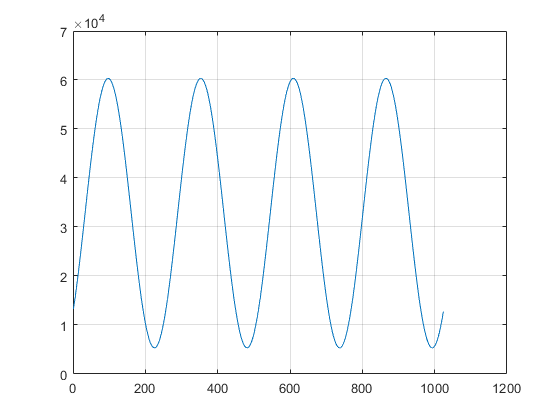

plot(inputBuf);
grid on;

clear dataIn dataInCmd cmd n

Получить выходной буфер от STM  <------

fopen(s);
cmd = [1 2];
fwrite(s,cmd,'uint16');
dataIn = fread(s,length(cmd),'uint16');
dataInCmd = dataIn(1,1);
if dataInCmd == 11
    stmOutBuf = zeros([dataIn(2,1),1],'single');
    for n = 1:length(stmOutBuf)
        stmOutBuf(n,1) = fread(s,1,'single');
    end
end
fclose(s);
disp(stmOutBuf);

   1.0e+07 *

    0.0033
    0.0000
    0.0000
    0.0000
    0.0027
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0

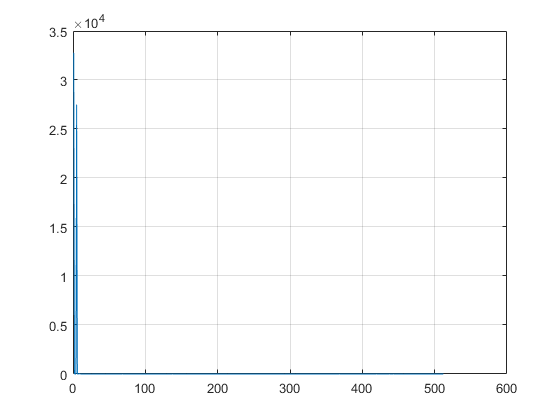

plot(stmOutBuf(1:length(stmOutBuf)/4));
grid on;

clear dataIn dataInCmd cmd n

Подготовить массив для записи

outBuf = zeros([DSP_LEN,1],'single');
for n=1:length(outBuf)
    outBuf(n) = input(n);
end
disp(outBuf);
clear n
plot(outBuf);
grid on;

Отправить данные STM

fopen(s);
cmd = [2 length(outBuf)];
fwrite(s,cmd,'uint16');
dataIn = fread(s,length(cmd),'uint16');
dataInCmd = dataIn(1,1);
if dataInCmd == 12
    stmReady = dataIn(2,1);
    if stmReady == 1
        fwrite(s,outBuf,'single');
    else
        fprintf('Stm not ready')
    end
end
fclose(s);
clear dataIn dataInCmd cmd stmReady